clc;clear;close all;

## 读取点

warning off
[num,txt,raw] = xlsread("八面安装点.xls");


phi = deg2rad(80);
shenglunum = 4;
a = 0.015*ones(1,2*shenglunum);
distanceThreshold = 0.02;



PAB = [1.987;-0.386;-0.153];
P_bound1 = num(1,[1,3,2]);
P_bound2 = num(2,[1,3,2]);

xl = num(5,~isnan(num(5,:)));
yl = num(7,~isnan(num(7,:)));
zl = num(6,~isnan(num(6,:)));
side_faces_transformed1 =[xl;yl;zl];

xt = num(10,~isnan(num(10,:)));
yt = num(12,~isnan(num(12,:)));
zt = num(11,~isnan(num(11,:)));
side_faces_transformed3 =[xt;yt;zt];

xr = num(15,~isnan(num(15,:)));
yr = num(17,~isnan(num(17,:)));
zr = num(16,~isnan(num(16,:)));
side_faces_transformed5 =[xr;yr;zr];


xb = num(20,~isnan(num(20,:)));
yb = num(22,~isnan(num(22,:)));
zb = num(21,~isnan(num(21,:)));
side_faces_transformed7 =[xb;yb;zb];


xlb = num(25,~isnan(num(25,:)));
ylb = num(27,~isnan(num(27,:)));
zlb = num(26,~isnan(num(26,:)));
side_faces_transformed8 =[xlb;ylb;zlb];


xlt = num(30,~isnan(num(30,:)));
ylt = num(32,~isnan(num(32,:)));
zlt = num(31,~isnan(num(31,:)));
side_faces_transformed2 =[xlt;ylt;zlt];


xrt = num(35,~isnan(num(35,:)));
yrt = num(37,~isnan(num(37,:)));
zrt = num(36,~isnan(num(36,:)));
side_faces_transformed4 =[xrt;yrt;zrt];

xrb = num(40,~isnan(num(40,:)));
yrb = num(42,~isnan(num(42,:)));
zrb = num(41,~isnan(num(41,:)));
side_faces_transformed6 =[xrb;yrb;zrb];


side_faces_transformed2 = [];
% side_faces_transformed4 = [];

[PlaneParaOut8,TrianglePoints8,MaxDis,distancesFianal] = planefit8(side_faces_transformed1,side_faces_transformed2,side_faces_transformed3,side_faces_transformed4,side_faces_transformed5,side_faces_transformed6,side_faces_transformed7,side_faces_transformed8,P_bound1,P_bound2,0.2);

Isempty FACE2468: 0.000000, 12.000000, 12.000000, 12.000000


Ti = ShengDaoGaoDu(shenglunum);
[PointTable_A_off8,PointTable_B_off8,XieMianPianYi,BianHao] = Calculate_rectangle_from_vertex8(side_faces_transformed1,side_faces_transformed2,side_faces_transformed3,side_faces_transformed4,side_faces_transformed5,side_faces_transformed6,side_faces_transformed7,side_faces_transformed8,P_bound1,P_bound2,PAB,phi,shenglunum,Ti,a,distanceThreshold)

Isempty FACE2468: 0.000000, 12.000000, 12.000000, 12.000000


PointTable_A_off8 =    -1.6750   -1.7726   -1.7733   -1.7739    0.3138    0.4134    0.4142    0.3273
   -1.3887   -1.5460   -1.5460   -1.5460    1.8530    2.0137    2.0137    1.8717
   -0.7639   -0.0005    1.0107    1.7858    1.7743    1.0124    0.0012   -0.7618


PointTable_B_off8 =    -1.0748   -1.1136   -1.1144   -1.1150   -0.2852   -0.2456   -0.2448   -0.2787
   -1.6285   -1.8094   -1.8094   -1.8094    2.0923    2.2770    2.2770    2.1138
   -0.7635    0.0000    1.0113    1.7863    1.7738    1.0119    0.0007   -0.7622


XieMianPianYi =     0.0091         0         0         0    0.0109         0         0   -0.0097


BianHao =      2     4     6     8     7     5     3     1
     1     3     5     7     8     6     4     2


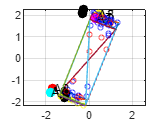

figure
hold on 
box on
grid on
axis equal
scatter3(side_faces_transformed1(1,:),side_faces_transformed1(2,:),side_faces_transformed1(3,:),15,'yellow')
% scatter3(side_faces_transformed2(1,:),side_faces_transformed2(2,:),side_faces_transformed2(3,:),15,'green')
scatter3(side_faces_transformed3(1,:),side_faces_transformed3(2,:),side_faces_transformed3(3,:),15,'red')
scatter3(side_faces_transformed4(1,:),side_faces_transformed4(2,:),side_faces_transformed4(3,:),15,'blue')
scatter3(side_faces_transformed5(1,:),side_faces_transformed5(2,:),side_faces_transformed5(3,:),15,'blue')
scatter3(side_faces_transformed6(1,:),side_faces_transformed6(2,:),side_faces_transformed6(3,:),15,'blue')
scatter3(side_faces_transformed7(1,:),side_faces_transformed7(2,:),side_faces_transformed7(3,:),15,'blue')
scatter3(side_faces_transformed8(1,:),side_faces_transformed8(2,:),side_faces_transformed8(3,:),15,'blue')
for i =1:16
    idt = [(i-1)*3+1:i*3,(i-1)*3+1];
    PointTri = TrianglePoints8(:,idt);
    plot3(PointTri(1,:),PointTri(2,:),PointTri(3,:));
end


% scatter3(ZhouDian(1,:),ZhouDian(2,:),ZhouDian(3,:),50,'filled','black')
% scatter3(PointTable_A_off8(1,:),PointTable_A_off8(2,:),PointTable_A_off8(3,:),50,'filled','black')
scatter3(PointTable_B_off8(1,:),PointTable_B_off8(2,:),PointTable_B_off8(3,:),50,'filled','black')


scatter3(PointTable_A_off8(1,1),PointTable_A_off8(2,1),PointTable_A_off8(3,1),50,'filled','r')
text(PointTable_A_off8(1,1),PointTable_A_off8(2,1),PointTable_A_off8(3,1),['A',num2str(BianHao(1,1))])


scatter3(PointTable_A_off8(1,2),PointTable_A_off8(2,2),PointTable_A_off8(3,2),50,'filled','g')
text(PointTable_A_off8(1,2),PointTable_A_off8(2,2),PointTable_A_off8(3,2),['A',num2str(BianHao(1,2))])

scatter3(PointTable_A_off8(1,3),PointTable_A_off8(2,3),PointTable_A_off8(3,3),50,'filled','b')
text(PointTable_A_off8(1,3),PointTable_A_off8(2,3),PointTable_A_off8(3,3),['A',num2str(BianHao(1,3))])

scatter3(PointTable_A_off8(1,4),PointTable_A_off8(2,4),PointTable_A_off8(3,4),50,'filled','c')
text(PointTable_A_off8(1,4),PointTable_A_off8(2,4),PointTable_A_off8(3,4),['A',num2str(BianHao(1,4))])

scatter3(PointTable_A_off8(1,5),PointTable_A_off8(2,5),PointTable_A_off8(3,5),50,'filled','m')
text(PointTable_A_off8(1,5),PointTable_A_off8(2,5),PointTable_A_off8(3,5),['A',num2str(BianHao(1,5))])

scatter3(PointTable_A_off8(1,6),PointTable_A_off8(2,6),PointTable_A_off8(3,6),50,'filled','y')
text(PointTable_A_off8(1,6),PointTable_A_off8(2,6),PointTable_A_off8(3,6),['A',num2str(BianHao(1,6))])

scatter3(PointTable_A_off8(1,7),PointTable_A_off8(2,7),PointTable_A_off8(3,7),50,'filled','y')
text(PointTable_A_off8(1,7),PointTable_A_off8(2,7),PointTable_A_off8(3,7),['A',num2str(BianHao(1,7))])

scatter3(PointTable_A_off8(1,8),PointTable_A_off8(2,8),PointTable_A_off8(3,8),50,'filled','k')
text(PointTable_A_off8(1,8),PointTable_A_off8(2,8),PointTable_A_off8(3,8),['A',num2str(BianHao(1,8))])



% scatter3(Pin(1),Pin(2),Pin(3),150,'r','filled')


% PP16 = TrianglePoints8(:,[7,8,14,20,26,32,38,44,3,9,18,24,30,36,42,48]);
% scatter3(PP16(1,2),PP16(2,2),PP16(3,2),50,'filled','red');
% scatter3(PP16(1,3),PP16(2,3),PP16(3,3),50,'filled','green');




## 点测试

% [PlaneParaOut4,TrianglePoints4,~,~] = planefit4(side_faces_transformed1,side_faces_transformed3,side_faces_transformed5,side_faces_transformed7,P_bound1,P_bound2,distanceThreshold);
% [Pin,Pout,UPP,b,h,w,Tao,PP] = Calculate_rectangle_from_vertex(TrianglePoints4)
% PP =PP';
% scatter3(PP(1,1),PP(2,1),PP(3,1),50,'r','filled')
% scatter3(PP(1,2),PP(2,2),PP(3,2),50,'g','filled')
% scatter3(PP(1,3),PP(2,3),PP(3,3),50,'b','filled')
% scatter3(PP(1,4),PP(2,4),PP(3,4),50,'c','filled')
% scatter3(PP(1,5),PP(2,5),PP(3,5),50,'m','filled')
% scatter3(PP(1,6),PP(2,6),PP(3,6),50,'y','filled')
% scatter3(PP(1,7),PP(2,7),PP(3,7),50,'k','filled')
% scatter3(PP(1,8),PP(2,8),PP(3,8),50,'r','filled')
% 
% scatter3(Pin(1),Pin(2),Pin(3),150,'r','filled')
% toff = [-a(1:shenglunum)./tan(phi),a(1:shenglunum)./tan(phi)];
% [PointTable_A_off,PointTable_B_off] = Calculat_JuXing_A_and_B_Points_after_Offest(Tao,UPP,Pin,b,h,PAB,phi,shenglunum,Ti,toff)
% 
% 
% scatter3(PointTable_B_off(1,1),PointTable_B_off(2,1),PointTable_B_off(3,1),150,'filled','r')
% scatter3(PointTable_B_off(1,2),PointTable_B_off(2,2),PointTable_B_off(3,2),150,'filled','g')
% scatter3(PointTable_B_off(1,3),PointTable_B_off(2,3),PointTable_B_off(3,3),150,'filled','b')
% scatter3(PointTable_B_off(1,4),PointTable_B_off(2,4),PointTable_B_off(3,4),150,'filled','c')
% scatter3(PointTable_B_off(1,5),PointTable_B_off(2,5),PointTable_B_off(3,5),150,'filled','m')
% scatter3(PointTable_B_off(1,6),PointTable_B_off(2,6),PointTable_B_off(3,6),150,'filled','y')
% 
% 
% scatter3(PointTable_B_off(1,8),PointTable_B_off(2,8),PointTable_B_off(3,8),150,'filled','k')
% scatter3(PointTable_B_off(1,:),PointTable_B_off(2,:),PointTable_B_off(3,:),50,'filled','black')